# Hamming Code

Based on the previous activities, the following code adds the 7-4hamming to the system to decrease the BER.

% ************************************************************************
% Author: CONG LI
% Date Created: 2023
%
% This script is part of a course project for 
% Communication Systems: Theory and Measurement M
% at University of Bologna.
% ************************************************************************
%% *2-ASK system (both transmitter and receiver) with Hamming coding*
% ************* Initialization of the environment*
clear all % clear all variables
close all % close all plots
warning off

   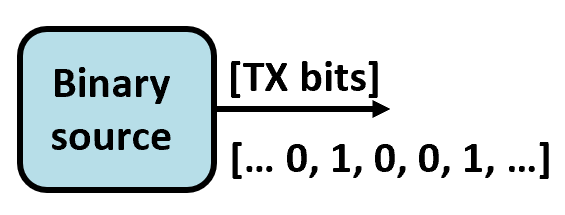

% ************* Signal specifications*
bits_per_symbol=1; % number of bits that correspond to a symbol
L=2^bits_per_symbol; % number of levels of the modulation alphabet
nbits=10000*bits_per_symbol; % number of bits to be transmitted
Br=500; % [bits/s] bit rate
fs=50000; % [samples/s] sampling frequency
Ts=1/fs; % sampling time[s].
fc=3000; % [Hz] carrier frequency
Bs=Br/log2(L); % [symbols/s] Symbol rate
nsps=fs/Bs; % samples per symbol

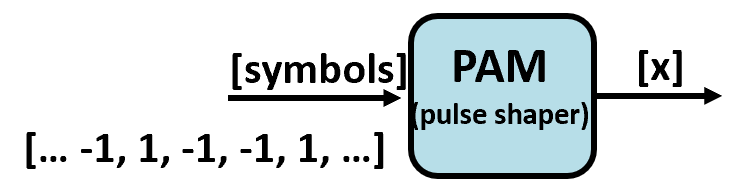

% ************* Pulse shaper specifications*
Nf=5*nsps; % number of filter coefficients for the pulse shaper
pulsetype='RECT';
switch pulsetype
case 'ROOTRAISEDCOSINE'
rolloff=0.8 % roll-off factor for root raised cosine pulses
bandwidth_Hz=0.5*Bs*(1+rolloff); % bandwidth of the baseband signal
case 'RECT' % rectangula pulse
rolloff=[];
bandwidth_first_lobe_Hz=Bs;
end

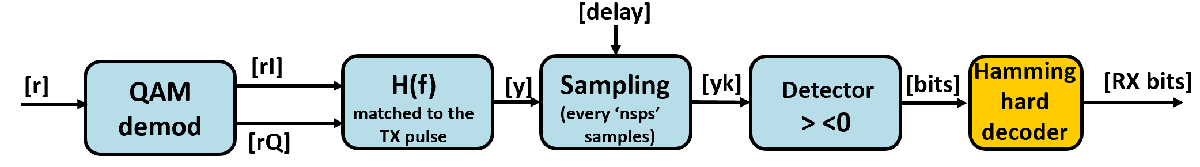

% ************* Demodulator specifications*
psi=0; % carrier offset at the receiver
% ************* Check on the number of bits to by coded by the Hamming encoder*
if rem(nbits,4)~=0 % The number of bits must be a multiple of 4
disp('The number of bits to e transmitted must be a multiple of 4')
return % The execution is stopped
end
% ************* Monte Carlo simulation
index=1;
for EbN0_dB=1:10% Run a Monte Carlo simulation for 10 different values of SNR
% ************* Source bits generation*
source_bits=BinarySource_2023(nbits); % vector with the source bits
% ************* Hamming coding*


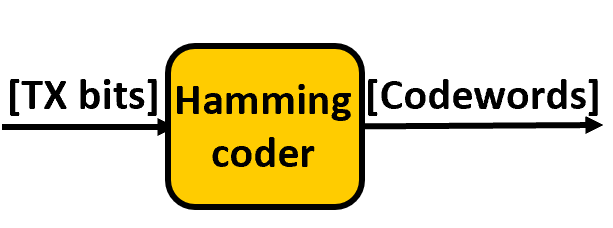

codedbits=HammingCoder_2023(source_bits); % Hamming coder
nCodedBits=length(codedbits);
% ************* Symbols generation with Gray mapping*
symbols=Encoder_2023(codedbits, L);
% ************* Generation of the baseband PAM signal*

[x,h,DelayPAM]=PAMmodulator_2023(symbols,nsps,Nf,pulsetype,rolloff);
T=Ts*(length(x)-1); % signal duration
% ************* 2-ASK modulation through the QAM modulator*


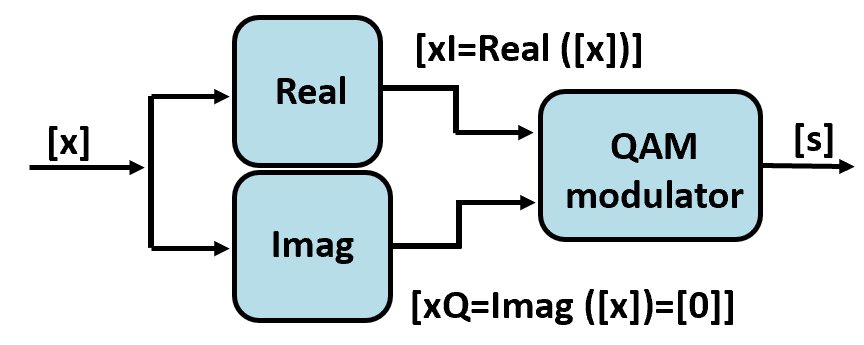

xI=x; % in-phase signal
xQ=zeros(1,length(x)); % the quadrature component is zero
s=ModQAM_2023(xI,xQ,fc,T,fs);
% ************ Noise generation and sum with the received signal*


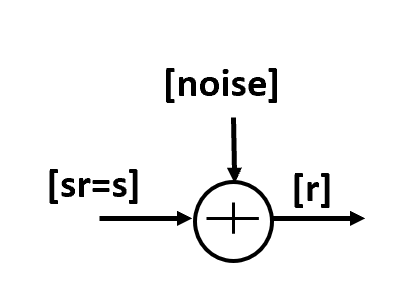

sr=s;
P=(1/length(sr))*sum(sr.^2); % Estimation of the mean power of the signal
EbN0=10^(0.1*EbN0_dB); % SNR expressed in linear units
sigman=sqrt(P*fs/(2*Br*EbN0)); % calculation of the noise's standard deviation
noise=sigman.*randn(1,length(sr)); % generation of the Gaussian noise
r=sr+noise; % addition of the noise to the received signal



% ************* QAM demodulator*


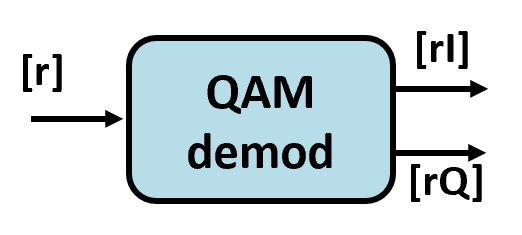

[rI,rQ,DelayQAM]=DeModQAM_2023(r,fc,T,fs,psi); % demodulate the signal
% ************* Matched filter*


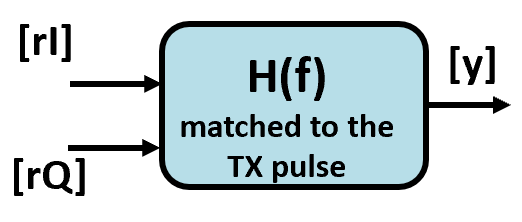

r=rI+1i*rQ;
y=conv(r,h)/nsps; % filtering with the matched filter
% ************* Sampler*


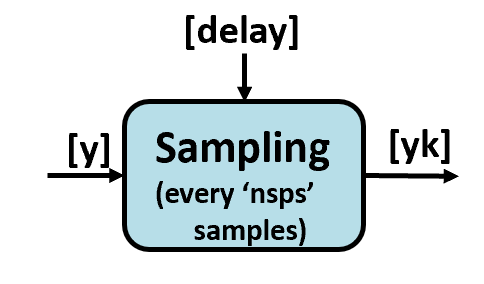

% compute the overall delay introduced by the TX and RX filters
delay=round (2*DelayPAM+DelayQAM);
% sample the signal every symbol time accounting for the delay
yk = y(delay:nsps:nsps*nCodedBits+delay-1);
% ************* Detector*


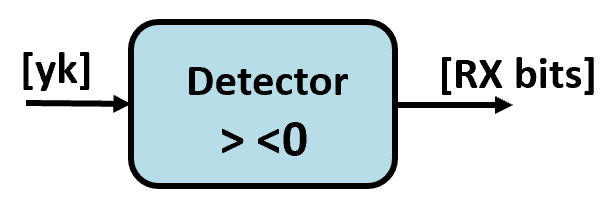

b=real(yk) > 0; % take only the real part
% ************* Hamming decoder*


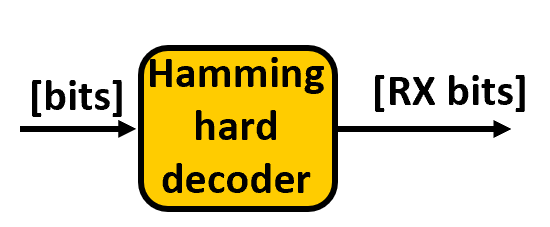

Compare the received (possibly wrong) codewords and check the table selecting the one with the minimum Hamming distance. 

RXdata=HammingHardDecoder_2023(b); % hard decoding

**Estimate the BER**

% ************* Bit Error Rate (BER) estimate*
noe=sum(abs(source_bits-RXdata)); % Errors count
nod=length(source_bits);
SNRdB(index)=EbN0_dB;

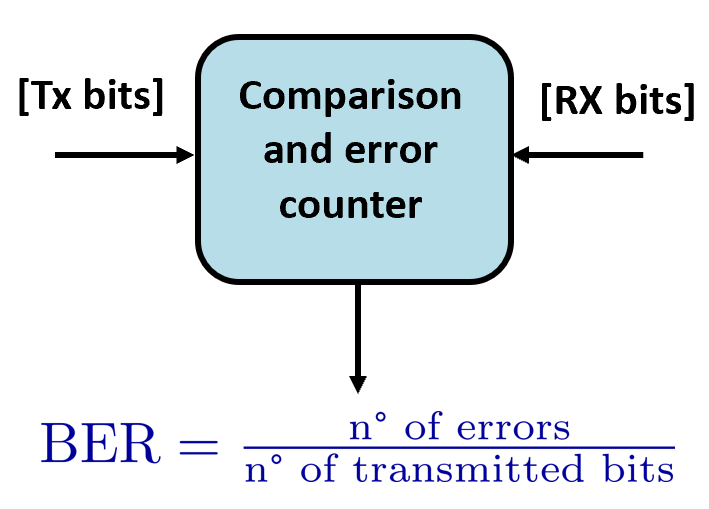

ber(index)=noe/nod; % Estimate the BER
fprintf('EbNo=%.1f (dB) BER=%g\n',SNRdB(index),ber(index));
index=index+1;
% ************* End of Monte Carlo simulation*
end

EbNo=1.0 (dB) BER=0.0272
EbNo=2.0 (dB) BER=0.0157
EbNo=3.0 (dB) BER=0.0049
EbNo=4.0 (dB) BER=0.0018
EbNo=5.0 (dB) BER=0.0005
EbNo=6.0 (dB) BER=0
EbNo=7.0 (dB) BER=0
EbNo=8.0 (dB) BER=0
EbNo=9.0 (dB) BER=0
EbNo=10.0 (dB) BER=0


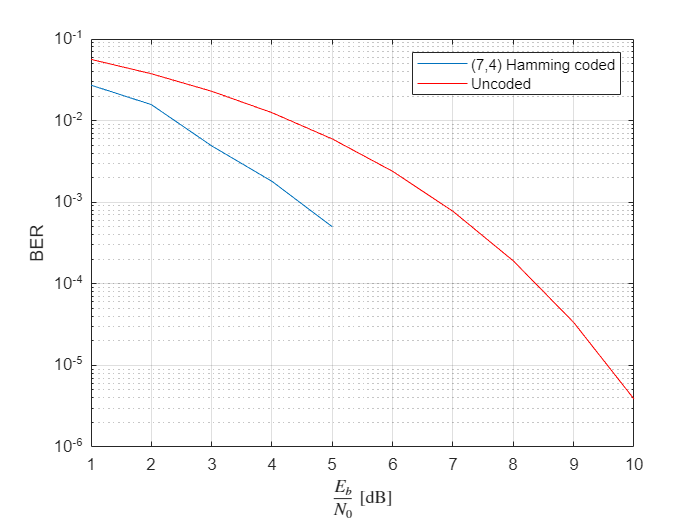


% ************* BER vs EbN0 plot*
figure
semilogy(SNRdB,ber);
xlabel('$\frac{E_b}{N_0}$ [dB]','HorizontalAlignment','center',...
'Interpreter','latex');
ylabel('BER');
grid on
hold on
SNR=10.^(0.1*SNRdB);
Pb=0.5*erfc(sqrt(SNR));
plot(SNRdB,Pb,'r')
legend('(7,4) Hamming coded', 'Uncoded')

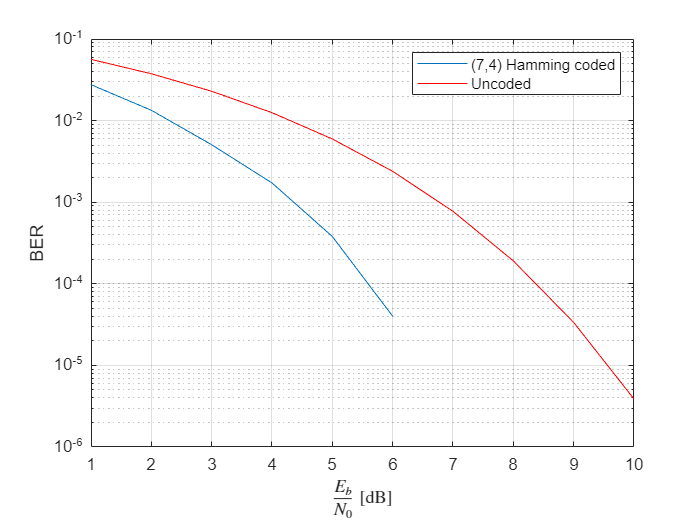

This picture is plotted with parameter nbits=50000*bits_per_symbol;

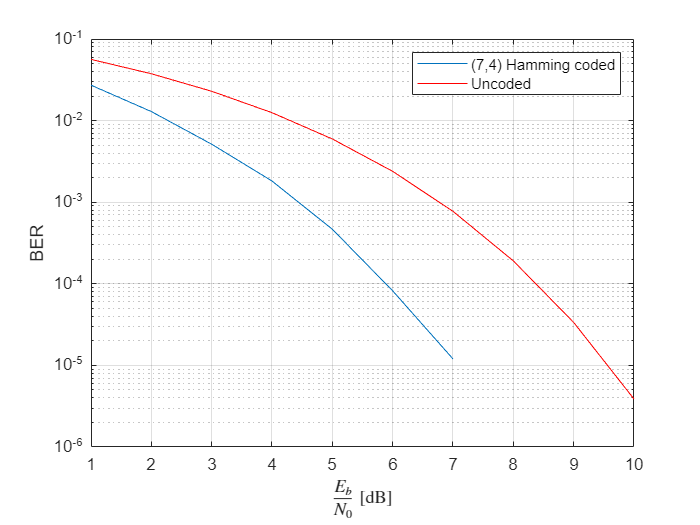

This picture is plotted with parameter nbits=100000*bits_per_symbol;

Overall, the error bit rate of 74 Hamming code and uncoded decreases with the increase of SNR, and 74 Hamming code can improve the SNR by 3db for the same case of error bit rate.The higher the signal-to-noise ratio, the more significant the signal quality improvement of Hamming code is.After simulating different number of bits, it was found that the simulation results were partially missing because the number of bits simulated was too low

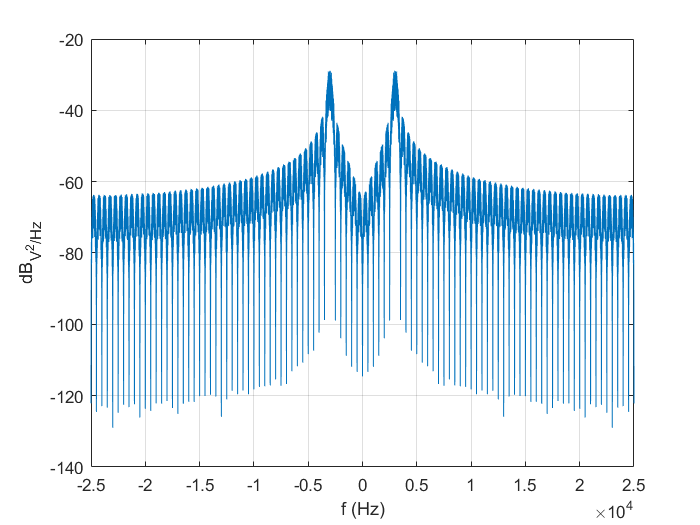

% ********* Spectrum plot
figure
PlotSpectrum_2023(s,fs);

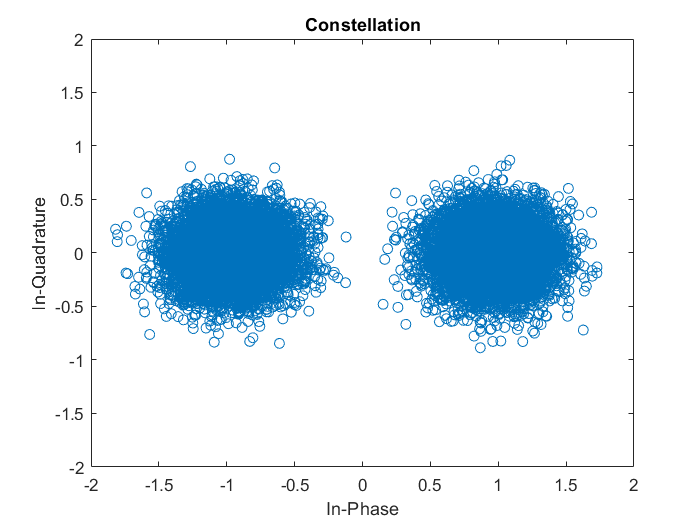

% ********* Constellation
x=real(yk);
y=imag(yk);
figure
plot(x,y,'o'), axis ([-2 2 -2 2]);
title('Constellation');
xlabel('In-Phase');
ylabel('In-Quadrature');

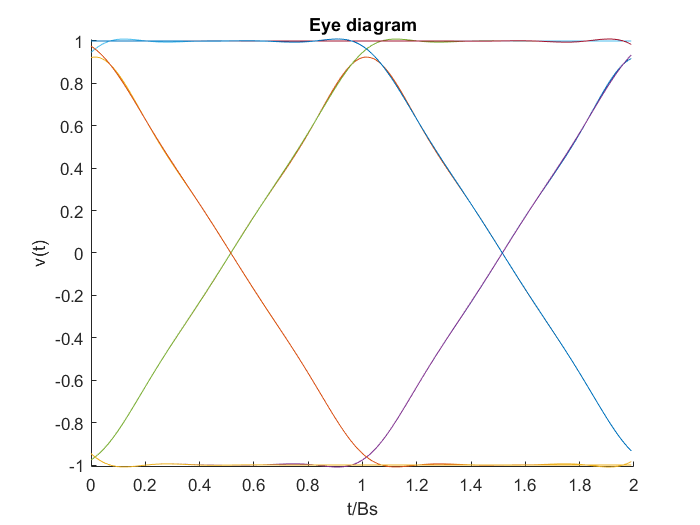

% ********* Eye diagram
H=2; % number of observation symbols
[yi,yq,DelayQAM]=DeModQAM_2023(sr,fc,T,fs,psi); % demodulate the signal
vt0=conv(yi,h)/nsps;
mm=max(abs(vt0));
x1=0:H*nsps-1;
x2=x1./nsps;
figure;
hold on
for iii=1:10
x=x1+iii*nsps+delay-1;
y=real(vt0(x)); % plot the in-phase via
plot (x2,y), axis([0 H -mm mm]);
end
title('Eye diagram');
xlabel('t/Bs');
ylabel('v(t)');